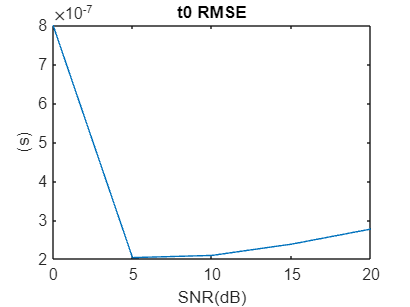

clear
clc

dir = "task3_2";
dir = dir+"/error_";
dBs = [20,15,10,5,0];
t0_RMSE = zeros(1,5);
f0_RMSE = zeros(1,5);
T_RMSE = zeros(1,5);
B_RMSE = zeros(1,5);

for i = 1:5
    file_dir = dir + int2str(dBs(i)) + "dB.mat";
    load(file_dir);
    t0_RMSE(i) = sqrt(sum((t0_error).^2,"all")/size(t0_error,1)/size(t0_error,2));
    f0_RMSE(i) = sqrt(sum((f0_error).^2,"all")/size(f0_error,1)/size(f0_error,2));
    T_RMSE(i) = sqrt(sum((T_error).^2,"all")/size(T_error,1)/size(T_error,2));
    B_RMSE(i) = sqrt(sum((B_error).^2,"all")/size(B_error,1)/size(B_error,2));
end

figure;
plot(dBs,t0_RMSE);
title("t0 RMSE");
xlabel("SNR(dB)");
ylabel("(s)");

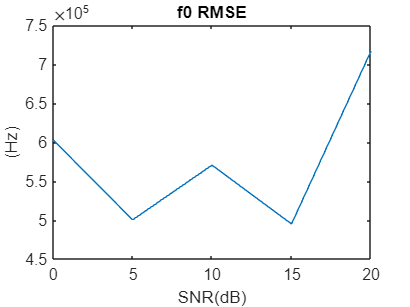


figure;
plot(dBs,f0_RMSE);
title("f0 RMSE");
xlabel("SNR(dB)");
ylabel("(Hz)");

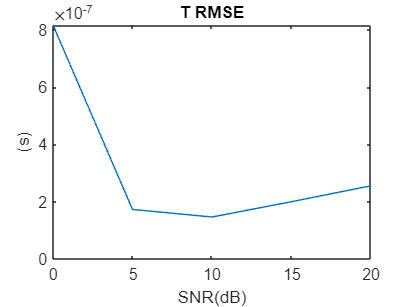


figure;
plot(dBs,T_RMSE);
title("T RMSE");
xlabel("SNR(dB)");
ylabel("(s)");

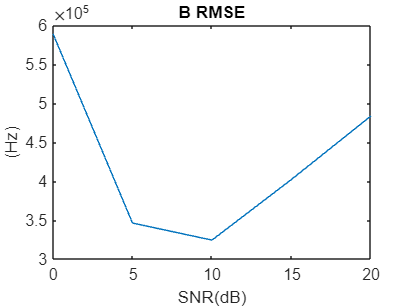


figure
plot(dBs,B_RMSE);
title("B RMSE");
xlabel("SNR(dB)");
ylabel("(Hz)");